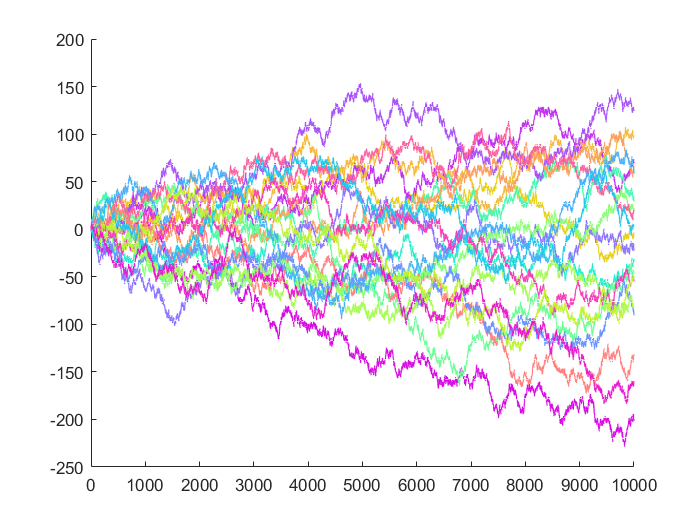

difference=[];
itterations=10000;
outputs=[];
rows=20;
for r=1:rows
    above=1;
    below=1;
    for i=1:itterations
        outputs(r,i)=sin(f(i,r));
        if(sin(f(i,r))>0)
            above=above+1;
        elseif(sin(f(i,r))<0)
            below=below+1;
        end
        difference(r,i)=above-below;
    end
end
%{
hold on
figure;
scatter(1:itterations,difference,1,'black','filled');
xlim([0 itterations])
hold off
%}
hold on
for r=1:rows
    scatter(1:itterations,difference(r,:),1,[abs(sin(r)),abs(sin(r+2*pi/3)),abs(sin(r+4*pi/3))],'filled');
end
xlim([0 itterations]);
hold off

function y = f(x,a)
    y=sin(x^((a+10)/10))*(x);
end